# Formating annotations for input into DeepAction

This example script demonstrates how to format existing annotations (i.e., those not annotated using the DeepAction annotation GUI) into $\texttt{.csv}
$ files that can be imported into a DeepAction project via the command $\texttt{project.ImportAnnotations(importTable)}$. The input argument $\texttt{importTable}$ is an *n* by 2 table, where *n* is the number of videos for which to import annotations, and columns $\texttt{VideoName}$ and $\texttt{FilePath}
$. For a given row, the entry in column $\texttt{VideoName}$ is the name of the video the annotations correspond to, and $\texttt{FilePath}$ the path to the $\texttt{.csv}$ file with the annotations.

To import the annotations, the $\texttt{.csv}$ files need to be formatted correctly, as follows:

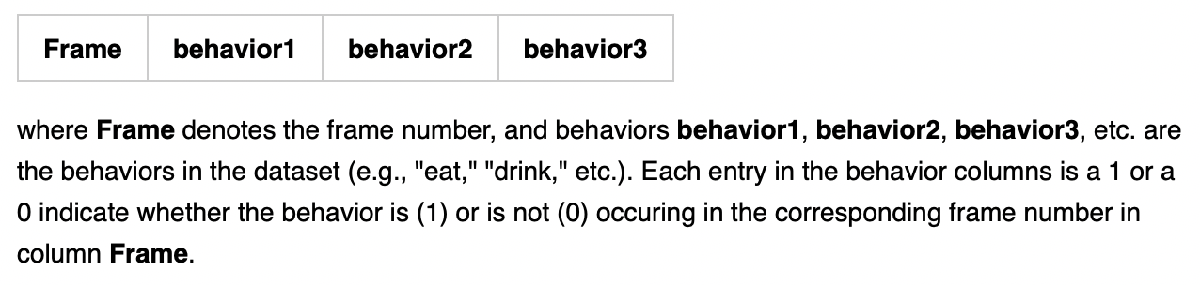

That is, the first column denotes the frame number. Subsequent columns denote whether or not the behavior corresponding to that column's header occurs in the frame specified by the $\texttt{Frame}$ column.

In the following sections, we demonstrate how to create .csv files with the correct input format using the annotations from annotation group 1 of the home-cage dataset. To begin, download the folder $\texttt{example\_annotations}$ found [here](https://drive.google.com/drive/folders/1jE6OKFNRZqhdqCmZ_--5uEfTUMBtxRnF?usp=sharing). It contains the set of .txt files to convert.

## Example

First, we need to collect all of the pre-annotated, unformatted .txt files that we'll convert. To do so, set annotationsFolder to the path to the $\texttt{example\_annotations}$ downloaded from the Google Drive.

annotationsFolder = '/Users/harriscaw/Documents/Behavior classification/Example datasets/example_annotations';

We then get all the .txt files in $\texttt{annotationsFolder}$:

annotFiles = dir(fullfile(annotationsFolder, '*.txt'));

Next, we consider the processing of a single .txt file into a correctly-formatted .csv file. To do so, we select the first .txt file in the folder:

currFile = fullfile(annotFiles(1).folder, annotFiles(1).name);
disp(currFile)

/Users/harriscaw/Documents/Behavior classification/Example datasets/example_annotations/20080321162447.txt


If you open the file currFile in your text editor, you'll see the first 3 lines are formatted as follows:

Where the first set of numbers in each row denotes the start of the behavior and the second set the end. The name of the behavior is shown at the end of each row.

Next, we use the helper function $\texttt{ParseTextFile}$ to convert this into a cleaner format:

parsedDataT = ParseTextFile(currFile);
disp(head(parsedDataT, 3))

        Behavior         Start    End
    _________________    _____    ___
    {'rest'         }       1     448
    {'micromovement'}     449     494
    {'walk'         }     495     641


This helper function creates, from each file, a table with the behavior name, and its start and end frame, as extracted from the .txt file.

Now that we have a more clearly formatted MATLAB table of the annotations contained in $\texttt{currFile}
$, we convert it to the format described at the beginning of this script. To do so, we use the helper function $\texttt{GetBehaviorArray}$:

ethogramT = GetBehaviorArray(parsedDataT);
disp(head(ethogramT, 10))

    Frame    drink    eat    groom    hang    micromovement    rear    rest    walk
    _____    _____    ___    _____    ____    _____________    ____    ____    ____
      1        0       0       0       0            0           0       1       0  
      2        0       0       0       0            0           0       1       0  
      3        0       0       0       0            0           0       1       0  
      4        0       0       0       0            0           0       1       0  
      5        0       0       0       0            0           0       1       0  
      6        0       0       0       0            0           0       1       0  
      7        0      

The table $\texttt{ethogramT}$ is correctly formatted, so we can use the function $\texttt{writetable}$ to export it to a .csv, and then import that .csv into out project via the $\texttt{ImportAnnotations}$ method.

## Processing all the files

Now we import each file in $\texttt{annotFiles}$ and save it to a .csv. To do so, specify $\texttt{outFolder}$ to be the folder where the annotations should be saved. In this section we also record cell arrays with video names, $\texttt{VideoName}$, and formatted .csv paths, $\texttt{FilePath}$, to demonstrate the proper formatting for the importation table.

outFolder = '/Users/harriscaw/Documents/Behavior classification/Example datasets/example_formatted';
disp(outFolder)

/Users/harriscaw/Documents/Behavior classification/Example datasets/example_formatted


if ~isfolder(outFolder)
    mkdir(outFolder)
end

VideoName = {};
FilePath = {};

for i = 1:length(annotFiles)
    currSrcPath = fullfile(annotFiles(i).folder, annotFiles(i).name);
    parsedDataT = ParseTextFile(currSrcPath);
    exportT = GetBehaviorArray(parsedDataT);
    
    [~, currVidName, ~] = fileparts(annotFiles(i).name);
    currDestPath = fullfile(outFolder, [currVidName, '.csv']);
    writetable(exportT, currDestPath);

    VideoName = [VideoName; currVidName];
    FilePath = [FilePath; currDestPath];
end

## Example importation table

Now, with arrays containing the video names and video paths, we can create the importation table:

importTable = table(VideoName, FilePath);
disp(head(importTable, 5))

         VideoName                                                           FilePath                                                   
    ___________________    _____________________________________________________________________________________________________________
    {'20080321162447' }    {'/Users/harriscaw/Documents/Behavior classification/Example datasets/example_formatted/20080321162447.csv' }
    {'20080324115556' }    {'/Users/harriscaw/Documents/Behavior classification/Example datasets/example_formatted/20080324115556.csv' }
    {'20080324143707A'}    {'/Users/harriscaw/Documents/Behavior classification/Example datasets/example_formatted/20080324143707A.csv'}
    {'20080324143707B'}    {'/Users/harriscaw/Documents/Behavior classification/Example datasets/example_formatted/20080324143707B.csv'}
    {'20080421153635' }    {'/Users/harriscaw/Documents/Behavior classification/Example datasets/example_forma

After instantiating an instance of a $\texttt{DeepActionProject}$ class, $\texttt{project}$, we could then import the annotations via: $\texttt{project.ImportAnnotations(importTable)}$.

## Helper functions

function parsedDataT = ParseTextFile(filePath)
Behavior = {};
Start = [];
End = [];

fileID = fopen(filePath,'r');
while ~feof(fileID)
    tline = fgetl(fileID);
    split_line = strsplit(tline,{' ','-'});
    
    Behavior = [Behavior; split_line(4)];
    Start = [Start; str2double(split_line{2})];
    End = [End; str2double(split_line{3})];
end
fclose(fileID);

parsedDataT = table(Behavior, Start, End);
end

function exportT = GetBehaviorArray(parsedDataT)
uniqueBehaviors = unique(parsedDataT.Behavior);

behaviorArray = zeros(max(parsedDataT.End), length(uniqueBehaviors));

for iRow = 1:size(parsedDataT, 1)
    currBehavior = parsedDataT.Behavior{iRow};
    currStart = parsedDataT.Start(iRow);
    currEnd = parsedDataT.End(iRow);
    
    currBehaviorIndex = find(strcmpi(currBehavior, uniqueBehaviors));
    behaviorArray(currStart:currEnd, currBehaviorIndex) = 1;
end

behaviorT = array2table(behaviorArray, "VariableNames",uniqueBehaviors);

Frame = [min(parsedDataT.Start):max(parsedDataT.End)]';
exportT = [table(Frame), behaviorT];
end